**INIT**

close all; clear all;

addpath(genpath('source'));

testImage = "lena.tif";
watermark = "res/pufferfish.mat";
alpha = 0.09;
resource = strcat("res/images/", testImage);
watermarked = strcat("outputs/watermarkedImages/", testImage);
attacked = strcat("outputs/attackedImages/", testImage);

**EMBED**

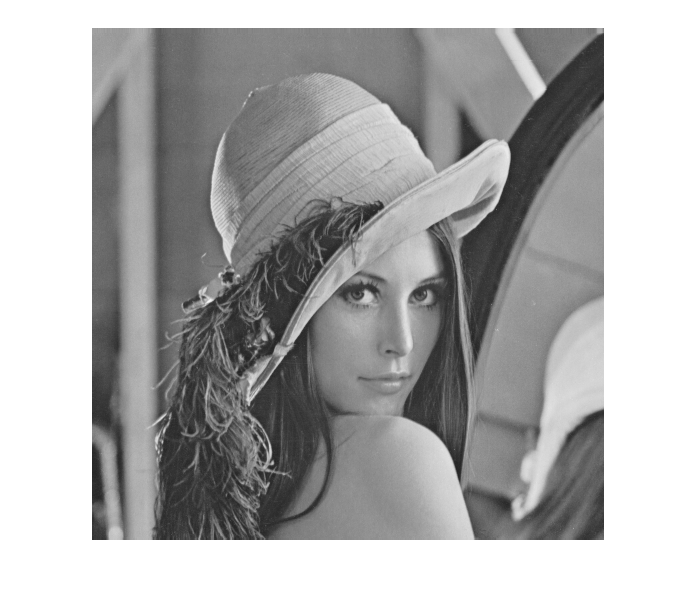

imwrite(embed(resource, watermark, alpha), watermarked, "tif");
imshow(resource);

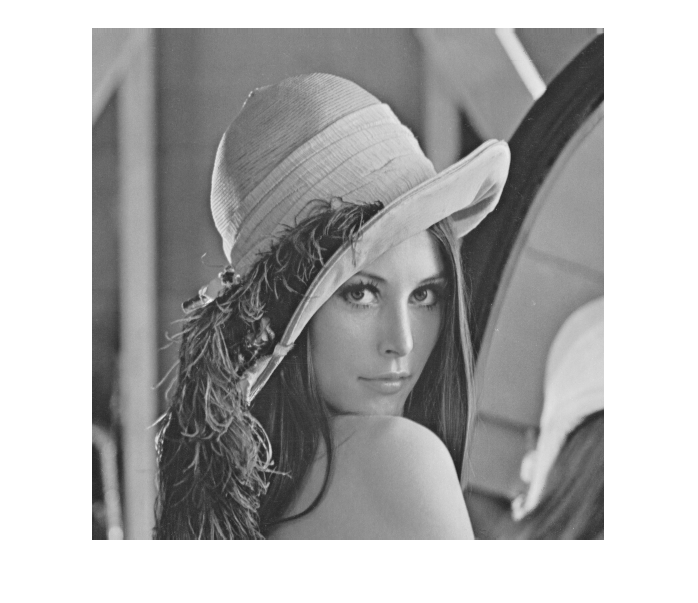

imshow(watermarked);


PSNR(imread(resource), imread(watermarked))

PSNR = +54.12 dB


WPSNR(imread(resource), imread(watermarked))

ans = 66.8720

**ATTACK**

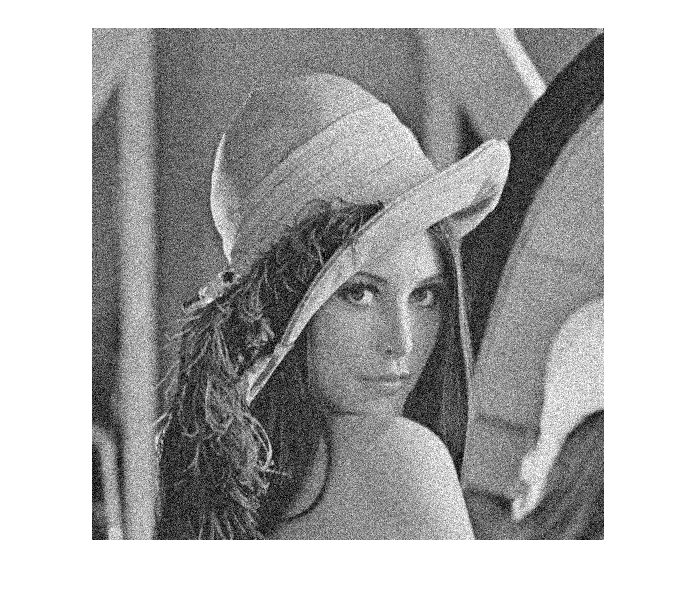

imwrite(attack(watermarked), attacked, "tif");
imshow(attacked);

PSNR(imread(watermarked), imread(attacked))

PSNR = +20.04 dB


WPSNR(imread(watermarked), imread(attacked))

ans = 35.2070

**DETECT**

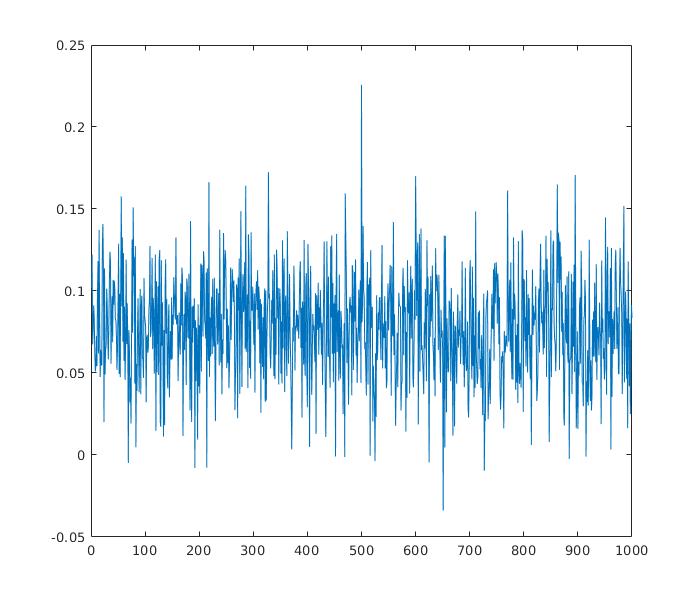

true


Output argument "detected" (and maybe others) not assigned during call to "detect".

[a, b] = detect(resource, watermarked, attacked, alpha);